

clc, clear, clearvars;

% Define parameters
num_elements_x = 9;  % Number of elements in x-direction
num_elements_y = 9;  % Number of elements in y-direction
nAntennas = num_elements_y*num_elements_x;

freq = 8e9;
c =  3e8;
lambda = c/freq;
d = lambda *0.536; % Element spacing (normalized)
SNR_dB = 5;
sigma2 = 1/(10^(SNR_dB/10))

sigma2 = 0.3162


% Define azim and elev intervals
azim_interval = [0, 180];
elev_interval = [90,270];

% Define number of sources
mSources = 1; % for now, becomes 2 when jamming is involved

% Define array geometry (Rectangular)
xcoords = -num_elements_x*d/2: d: num_elements_x*d/2;
ycoords = -num_elements_y*d/2: d: num_elements_y*d/2

ycoords =    -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905


% span out the basis vectors
[x_span, y_span] = meshgrid(xcoords, ycoords)

x_span =    -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905
   -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905
   -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905
   -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905
   -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905
   -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905
   -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905
   -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905
   -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503    0.0703    0.0905
   -0.0905   -0.0703   -0.0503   -0.0302   -0.0101    0.0101    0.0302    0.0503  

y_span =    -0.0905   -0.0905   -0.0905   -0.0905   -0.0905   -0.0905   -0.0905   -0.0905   -0.0905   -0.0905
   -0.0703   -0.0703   -0.0703   -0.0703   -0.0703   -0.0703   -0.0703   -0.0703   -0.0703   -0.0703
   -0.0503   -0.0503   -0.0503   -0.0503   -0.0503   -0.0503   -0.0503   -0.0503   -0.0503   -0.0503
   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302   -0.0302
   -0.0101   -0.0101   -0.0101   -0.0101   -0.0101   -0.0101   -0.0101   -0.0101   -0.0101   -0.0101
    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101    0.0101
    0.0302    0.0302    0.0302    0.0302    0.0302    0.0302    0.0302    0.0302    0.0302    0.0302
    0.0503    0.0503    0.0503    0.0503    0.0503    0.0503    0.0503    0.0503    0.0503    0.0503
    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703    0.0703
    0.0905    0.0905    0.0905    0.0905    0.0905    0.0905    0.0905    0.0905  



% Generate a grid of azimuthal and elevation angles
azim_basis = linspace(azim_interval(1), azim_interval(2), 180);
elev_basis = (linspace(elev_interval(1), elev_interval(2), 180));
% Define a vector space that spans the antenna coords
[azim_span, elev_span] = meshgrid(azim_basis, elev_basis);


EF = 1.5;
EP = cosd(azim_span).^(EF/2);  % Corrected element pattern calculation


% Define steering vector as anon function
steer_vec = @(azim, elev, x, y) exp(1j*2 * (pi/lambda) * ...
    (x * sind(elev) .* cosd(azim) + y * sind(elev) .* sind(azim)));

% Define anon function to take hermitian
hermy = @(complex_matrix) conj(complex_matrix')

hermy = function_handle with value:
    @(complex_matrix)conj(complex_matrix')


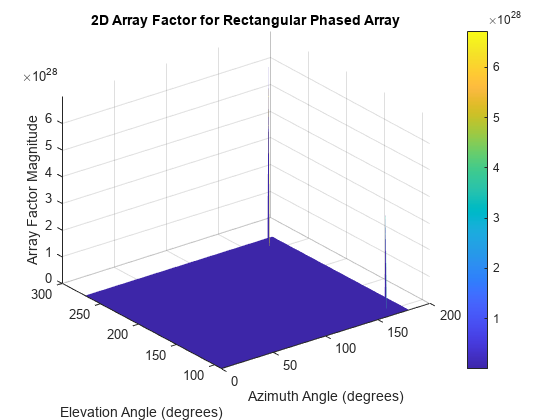


% Compute psuedospectrum
pSpectrum = zeros(size(azim_span));


%Define plane trajectory
plane_path_azim = (linspace(azim_interval(1), azim_interval(2), 180));
plane_path_elev = linspace(elev_interval(1), elev_interval(2), 180);

% Set up the figure
figure;
ax = axes;
h = surf(ax, azim_basis, elev_basis, abs(pSpectrum), 'EdgeColor', 'none');
title('2D Array Factor for Rectangular Phased Array');
xlabel('Azimuth Angle (degrees)');
ylabel('Elevation Angle (degrees)');
zlabel('Array Factor Magnitude');
colormap(parula)

colorbar;


for k = 1:180
    
    azim_doa = plane_path_azim(k);
    elev_doa = plane_path_elev(k);

    % Compute steering matrix
    steer_matrix = steer_vec(azim_doa, elev_doa, x_span, y_span);
        
    
    % Analytically compute spacial covariance matrix
    signalCov = (steer_matrix * (steer_matrix'))/(nAntennas);
    noiseCov = eye(length(steer_matrix))*sigma2;
    spacialCov = signalCov + noiseCov;
    
    
    % Compute eignendecomposition on spacial covariance matrix
    [eigenvectors, eigenvalueDiagonal] = eig(spacialCov);
    
    % Extract eigenvalues
    eigenvalues = diag(eigenvalueDiagonal);
    
    % Sort eigenvalues and corresponding eigenvectors
    [sortedEigenvalues, idx] = sort(eigenvalues);
    sortedEigenvectors = eigenvectors(:, idx);
    
    
    % Calculate the rank of both the noise and signal eigenspaces
    noise_eigenRank = length(idx) - mSources;
    signal_eigenRank = mSources;
    
    % Compute noise eigenspace ( eigenspaces span their eigenvectors )
    noiseEigenspace = sortedEigenvectors(:, 1:noise_eigenRank);
    signalEigenspace = sortedEigenvectors(:, end - signal_eigenRank:end);
    
    % Compute psuedospectrum
    pSpectrum = zeros(size(azim_span));
    
    for i = 1:length(azim_basis)    
  
        for j = 1:length(elev_basis)
    
        % Define DOA
        azim_i = azim_basis(i);
        elev_i = elev_basis(j);
    
        % Compute steering matrix
        steer_matrix = steer_vec(azim_i, elev_i, x_span, y_span);
        %Flatten to work/interface with matrix multiplications
        flat_steer_matrix = steer_matrix(:);

        % compute novel numerator
        signalInnerProd = signalEigenspace*(signalEigenspace');
        %num = (flat_steer_matrix'*signalInnerProd(:));

    
        % Compute Music
        music_matrix = (conj(steer_matrix)' * (noiseEigenspace * conj(noiseEigenspace)') * steer_matrix);
        music_matrix = ((steer_matrix)' * (noiseEigenspace * (noiseEigenspace)') * steer_matrix);

        music_vec = music_matrix(:);
        
        %music_element = trace(music_matrix);
        music_element = (music_vec')*music_vec;
        pSpectrum(i,j) =1/music_element;
       
        end
    end

        % Convert to dB
        pSpectrum = (abs(pSpectrum.*EP));
        pSpectrum_dB = 10*log10(pSpectrum/max(max(pSpectrum))).*EP;
    
        % Update and draw the plot
        set(h, 'ZData', (pSpectrum));
        colormap(parula);

        hold on;
        % Find the indices of the maximum value in pSpectrum
        [maxVal, maxIdx] = (max(pSpectrum(:)));
    
        % Convert linear index to row and column indices
        [maxRow, maxCol] = ind2sub(size(pSpectrum), maxIdx);
    
        % Plot red dot at the location of the peak
        %scatter3(ax, azim_span(maxRow, maxCol), elev_span(maxRow, maxCol), maxVal, 'ro', 'filled');
    
        % Plot white dot at the direction of arrival
        %scatter3(ax, azim_doa, elev_doa, maxVal, 'go', 'filled');

        drawnow

end